# Signal and Image Processing

# Lab 1 - Introduction to Image Analysis with Matlab

## Question 1.1

First load the two images. We have provided the code for one (assuming that the image is in the same folder as the "current folder" is)... add the code for the second one yourself!

[im1, map1] = imread('sg1_gray.tiff');
% load the second image too
[im2, map2] = imread('sg1_RGB.tiff');

Now display the images. Note that we already provided some of the code to make things look nice. Also do it without those commands such that you understand what they are doing.

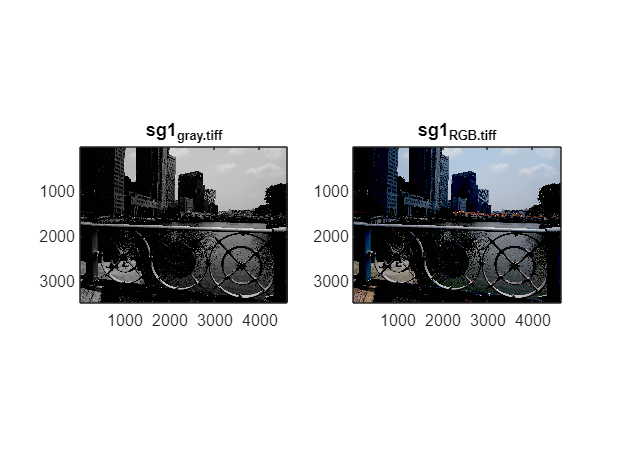

figure(1)
subplot(1,2,1);
% The command for displaying the forst image goes here
image(im1)
% Here you ensure that the proper colormap is used
colormap(map1)

axis image
title('sg1_gray.tiff');

subplot(1,2,2);
% Here goes the command for displaying the second image 
image(im2)
% cannot use "colormap(map2)" because map2 = empty as rgb image

title('sg1_RGB.tiff');
axis image

question was to know the properties of the image so let's do that:

info1 = imfinfo("sg1_gray.tiff")

info1 = struct with fields:
                     Filename: 'C:\Users\jules\OneDrive\Documents\Maastricht (DSDM)\Master\Year 1\Sept-Jan\KEN4222 SIP\LAB1 - image analysis\sg1_gray.tiff'
                  FileModDate: '12-Sep-2023 10:32:37'
                     FileSize: 7459204
                       Format: 'tif'
                FormatVersion: []
                        Width: 4632
                       Height: 3474
                     BitDepth: 8
                    ColorType: 'indexed'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB Palette'
                 StripOffsets: [8 88326 180346 268749 356884 444151 527019 612198 703393 794190 880472 975436 1081283 1177275 1263457 1357513 1454351 1546087 1642001 1747340 1857968 1969277 2080920 2196611 2312166 2420313 2509794 … ] (1×65 double)
              

% wanted data is : width, height, image color type, image data type
all_info1 = [string(info1.Width); string(info1.Height); info1.ColorType; "uint8"];
all_info1

all_info1 = 4×1 string array
    "4632"
    "3474"
    "indexed"
    "uint8"



info2 = imfinfo("sg1_RGB.tiff")

info2 = struct with fields:
                     Filename: 'C:\Users\jules\OneDrive\Documents\Maastricht (DSDM)\Master\Year 1\Sept-Jan\KEN4222 SIP\LAB1 - image analysis\sg1_RGB.tiff'
                  FileModDate: '12-Sep-2023 10:32:35'
                     FileSize: 33488156
                       Format: 'tif'
                FormatVersion: []
                        Width: 4632
                       Height: 3474
                     BitDepth: 24
                    ColorType: 'truecolor'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: [8 8 8]
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB'
                 StripOffsets: [8 669996 1337225 2009441 2679341 3350902 4016892 4683175 5354057 6020319 6686082 7348704 8013993 8665746 9301276 9939425 10538796 11115317 11660599 12235782 12806422 13370611 13939431 14508766 15074557 … ] (1×65 double)
         

% wanted data is : width, height, image color type, image data type
all_info2 = [string(info2.Width); string(info2.Height); info2.ColorType; "uint8"];
all_info2

all_info2 = 4×1 string array
    "4632"
    "3474"
    "truecolor"
    "uint8"


## Question 1.2

First load the image we need

% get rid of the variables that are in the workspace
clear
% load the built-in image (this will generate variables X, caption and map)
load mandrill

Now it is up to you to convert and save it.

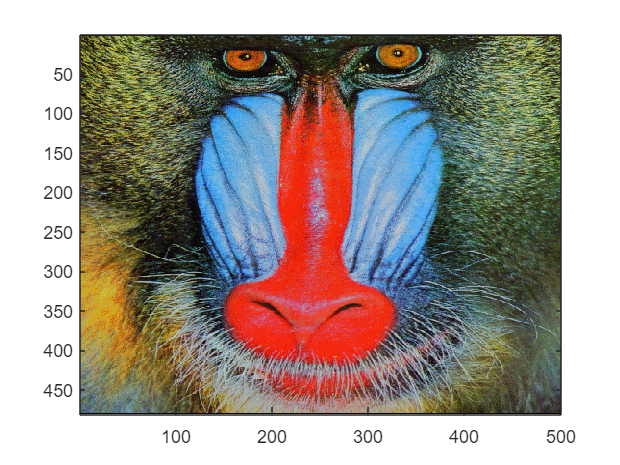

% Conversion to RGB goes below
mandrillRGB= ind2rgb(X, map);
figure, image(mandrillRGB)

% Saving it goes here
imwrite(mandrillRGB, map, 'mandrill.bmp')

Next implement the function rgbtograyscale. Create a file named rgbtograyscale.m in the same folder as this file and start with the line as indicated in the assignment. Then use it:

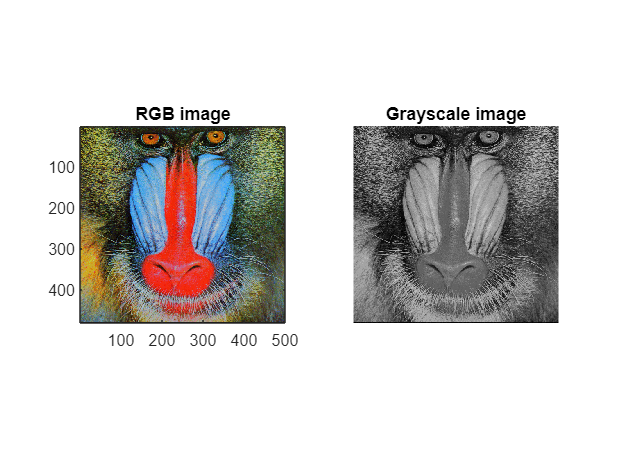

mandrill_gray=rgbtograyscale(mandrillRGB);

figure(2)
subplot(1,2,1);
image(mandrillRGB);
title('RGB image')
axis image
subplot(1,2,2);
imshow(mandrill_gray);
title('Grayscale image')
axis image


%% resulting images are ok!

## Question 1.3

First load things and stuff

clear
[im1, map1] = imread('sg1_gray.tiff');
[im3, map3] = imread('man.bmp');

Display the images and their histograms

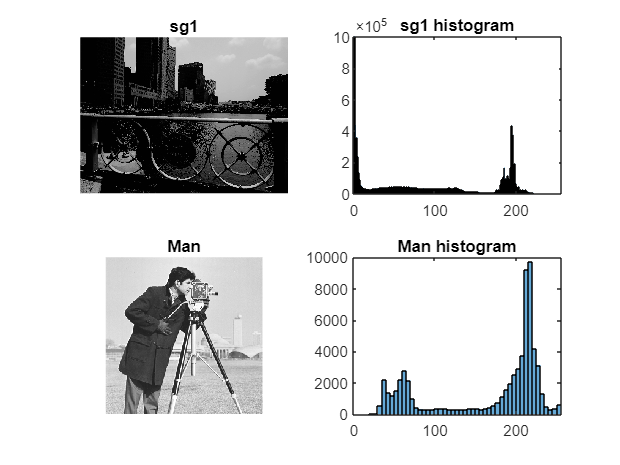

figure
subplot(2,2,1);
% Show first image
imshow(im1)
title('sg1')
axis image

subplot(2,2,2);
% Show the histogram of the first image
histogram(im1)
title('sg1 histogram')
axis([0,255,0,1000000]); % you might need to correct the axis


subplot(2,2,3);
% Show the second image
imshow(im3)
title('Man')
axis image

subplot(2,2,4);
% Show the histogram of the second image
histogram(im3)
title('Man histogram')
axis([0,255,0,10000]); % you might need to correct something

You should now be able to answer sub a) sg1 histogram shows the black and dark gray tones as shown with the spike around 0. The man image has more light gray tones as is shown zith the 200-ish spike. 

For sub b) you have to implement a function histogramequalization.m. We've provided how we generated the images in the slides below. You can use it to create your own function.

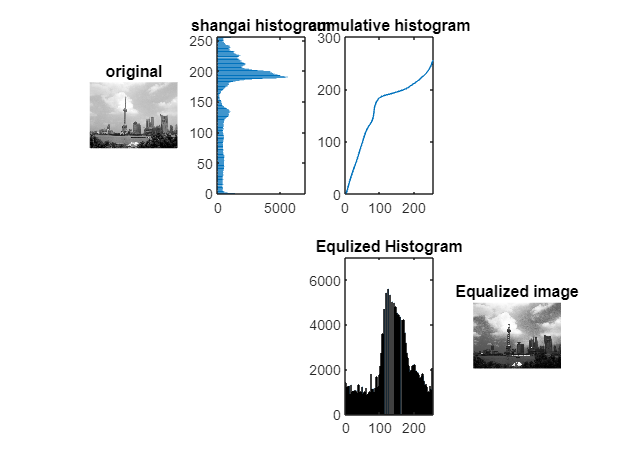

C=imread('example_shanghai_gray.bmp');

figure
subplot(2,4,1);
imshow(C);
title original

subplot(2,4,2);
hg=histcounts(double(C(:)),-0.5:255.5);
barh(0:255,(hg));axis([0,7000,-0.5,255.5]);%axis off
title('shangai histogram')

subplot(2,4,3)
plot(255*cumsum(hg)/241968,0:255);%axis tight off
title('cumulative histogram')

D = histogramequalization(C); % own hist equl function
%D=histeq(C); % this is how Matlab does it

% Manually we can do it as:
% T=cumsum(hg);
% T=T/T(end);
% D=zeros(size(C));
% for cnt1=1:size(D,1)
%     for cnt2=1:size(D,2)
%         D(cnt1,cnt2)=256*T(C(cnt1,cnt2)+1);
%     end
% end
% D=floor(D);

subplot(2,4,7)
histogram(double(D(:)),-0.5:255.5);axis([-0.5,255.5,0,7000]);%axis off
title('Equlized Histogram')

subplot(2,4,8)
imshow(D);
title('Equalized image')

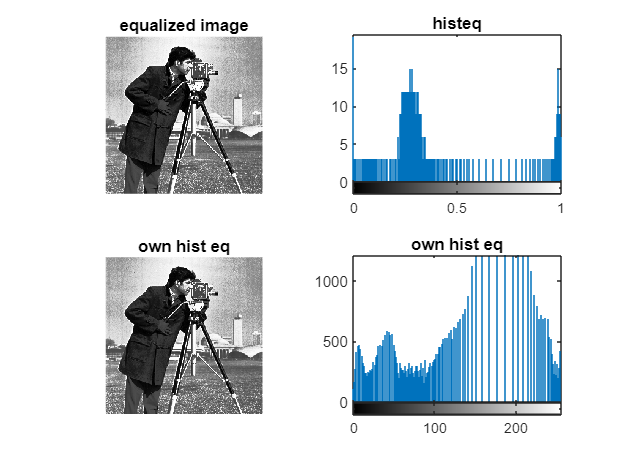



%%%%% c)
%Compare both methods (matlab and mine)
eq_im = histeq(im3, map3);
self_eq_im = histogramequalization(im3);

figure
subplot(2,2,1)
imshow(histeq(im3))
title('equalized image')
subplot(2,2,2)
imhist(eq_im)
title('histeq')

subplot(2,2,3)
imshow(self_eq_im)
title('own hist eq')
subplot(2,2,4)
imhist(self_eq_im)
title('own hist eq') 

b) To answer b, it is clear that with any image the graphs show that the concentrations have shifted. We have achieved are more balanced intensitiy of values, that is, a more uniform distribution of intensity values. This is true for both the shangai and the man images.

Now you need to do the sub c) and d)

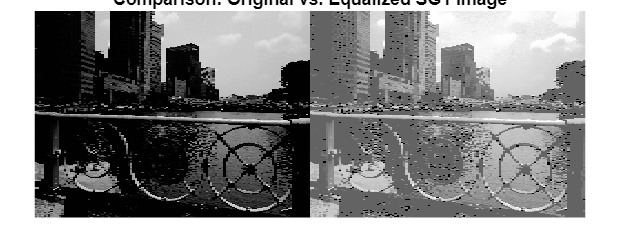

% Code goes here

%d)
%sg1
figure;
imshowpair(im1, histogramequalization(im1), 'montage');
title('Comparison: Original vs. Equalized SG1 Image');
axis image;

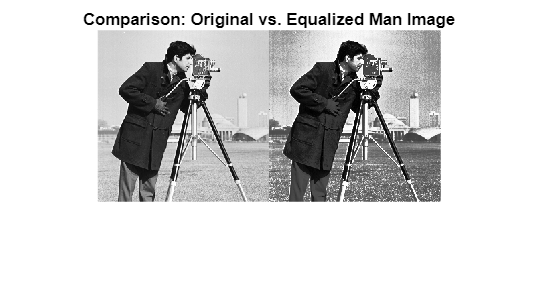

%man 
figure;
imshowpair(im3, histogramequalization(im3), 'montage');
title('Comparison: Original vs. Equalized Man Image');
axis image;

We can observe that for both the image contrast was increased. For the man image it is quite easy to see that the edges are clearer after the equalization, hence, features are more distinguishable because better contrast. 

For the SG1 image it is less pleasant to the eye, because the contrast has just increased by too little.

## Question 1.4

implement the linearscale.m function as requested

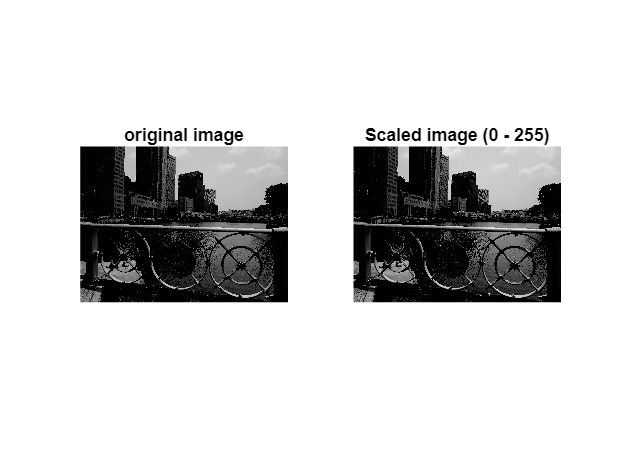

% figure
% % original image
% subplot(1,2,1)
% image(im1);
% colormap(map1)
% title('sg1')
% axis image off
% % linear scaled from 0 to 255

sg1_scaled = linearscale(im1, 0, 255);
figure
subplot(1,2,1)
imshow(im1)
title('original image')

subplot(1,2,2)
imshow(sg1_scaled)
title('Scaled image (0 - 255)')


avg_sg1 = mean(im1(:));
avg_scaled= mean(sg1_scaled(:));
fprintf(['avg pixel value for \n original image :',num2str(avg_sg1),' \n scaled image: ',num2str(avg_scaled), '.'])

avg pixel value for 
 original image :59.864 
 scaled image: 62.5407.

## Question 1.5

Load the data and display the image

clear
eye = imread('eye.png');
figure
subplot(2,2,1);
image(eye);
axis image
title('original')
subplot(2,2,2);
hist(eye(:),0:255);
axis([0,255,0,22000]);
title('original histogram')

Use slicing and thresholding to get what you want

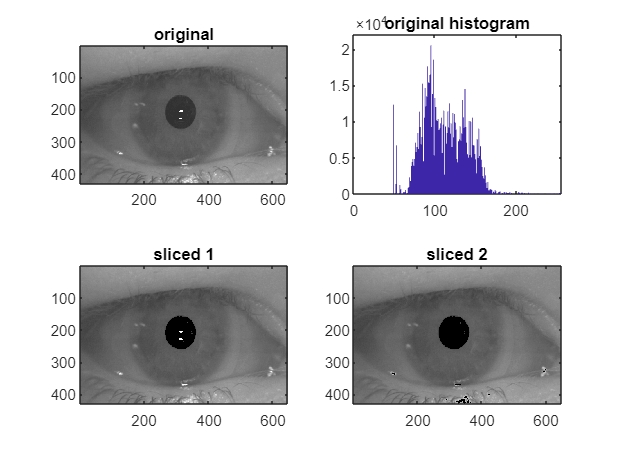



sliced=eye;
% Modify it further here
% Display intermediate results
sliced(sliced<63)=0;

subplot(2,2,3);
image(sliced);
axis image
title('sliced 1')


% Modify some more
% Display end result
double_sliced=eye;
double_sliced(double_sliced<63)=0;
double_sliced(double_sliced>200)=0;
subplot(2,2,4);
image(double_sliced);
axis image
title('sliced 2')

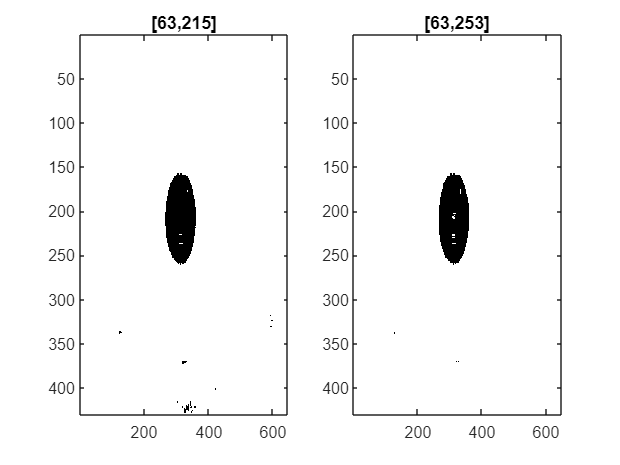



%do slicing with the threshold values to show only the pupil without the white parts
figure
subplot(1,2,1)
image(eye<215 & eye>63)
title('[63,215]')

subplot(1,2,2)
image(eye<253 & eye>63)
title('[63,253]')

## Question 1.6

a) Load the image and determine dimensions

clear
Z = imread('mandrill.bmp');
% Code for finding out dimensions goes here
fprintf(['the dimensions are ', num2str(size(Z))])

the dimensions are 480  500    3

size(Z)

ans =    480   500     3


b) We generate the new variables

im1 = Z(:,:,1);
im2 = Z(:,:,2);
im3 = Z(:,:,3);
im = double([im1(:) im2(:) im3(:)]);

Figure out the size of the new image

size_new = size(im)

size_new =       240000           3


size_new

size_new =       240000           3


% what is the difference with size(Z)? --> 480*500 = 240 000

Determine the size of the original image and put it in nc (number of columns) and nr (number of rows)

% code goes here
[nr, nc, channels] = size(Z);

%could have also done size(Z, 1-2 or 3) depending on what we want

And now let's try

imRED = reshape(im(:,1), nr, nc);
imGREEN = reshape(im(:,2), nr, nc);
imBLUE = reshape(im(:,3), nr, nc);

d) Display the images

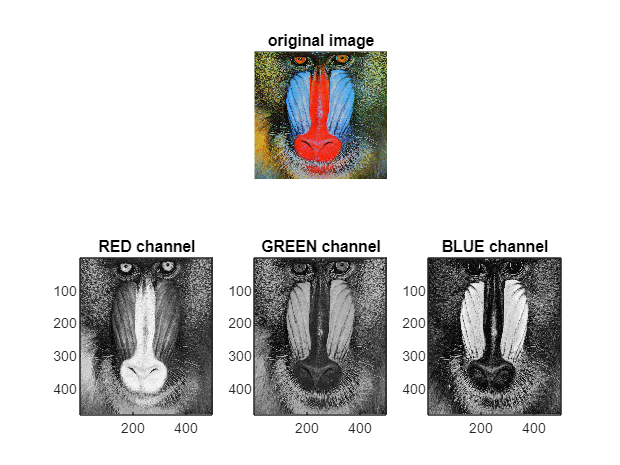

figure
subplot(2, 3, 2)
imshow(Z)
title('original image')


%%% ATTENTION the following works with "image()" not with "imshow() --> Feature	                image()	imshow()
                                                                       %Applies color mapping	    No	   Yes
                                                                       %Max. number of dimensions	Any	    3
subplot(2,3,4)
colormap gray % NOT REALLY NEEDED I GUESS
image(imRED)
title('RED channel')

subplot(2,3,5)
image(imGREEN)
title('GREEN channel')

subplot(2,3,6)
image(imBLUE)
title('BLUE channel')



% figure
% subplot(2,2,1)
% % Display something
% axis image
% title('original')
% subplot(2,2,2)
% % Display something
% colormap gray
% axis image
% title('imRED')
% subplot(2,2,3)
% % Display something
% colormap gray
% axis image
% title('imGREEN')
% subplot(2,2,4)
% % Display something
% colormap gray
% axis image
% title('imBlue')

Determine what witchcraft has happened: as the 3 channels are now split in R G and B individually, the pixels now each have one row so grayscale.

e) implement the function rgbtohsi.m and test it

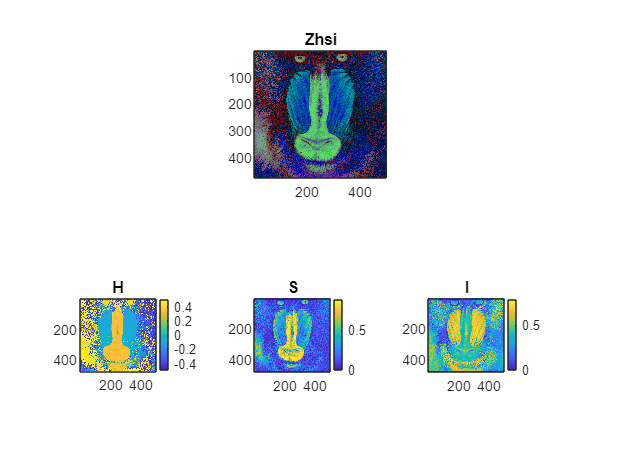

% I've programmed it that it works on the images directly
Zhsi=rgbtohsi(Z);

H = Zhsi(:,:,1);
S = Zhsi(:,:,2);
I = Zhsi(:,:,3);

figure;
subplot(2,3,2)
image(Zhsi)
axis image
title('Zhsi')

subplot(2,3,4)
imagesc(H)
colorbar
axis image
title('H')

subplot(2,3,5)
imagesc(S)
colorbar
axis image
title('S')

subplot(2,3,6)
imagesc(I)
colorbar
axis image
title('I')

## Question 1.7

% create the signal
i = 1;
signal = 1;
s = []


s =

     []





while signal > 0
    if i <= 6
        signal = 2^i;
        i = i + 1;
    else
        if signal > 63
            signal = signal -1;
        else
            signal = signal -2;
        end
    end

    if signal <0 
        break
    end 

    s = [s, signal]
    
end

s = 2

s =      2     4


s =      2     4     8


s =      2     4     8    16


s =      2     4     8    16    32


s =      2     4     8    16    32    64


s =      2     4     8    16    32    64    63


s =      2     4     8    16    32    64    63    61


s =      2     4     8    16    32    64    63    61    59


s =      2     4     8    16    32    64    63    61    59    57


s =      2     4     8    16    32    64    63    61    59    57    55


s =      2     4     8    16    32    64    63    61    59    57    55    53


s =      2     4     8    16    32    64    63    61    59    57    55    53    51


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11     9


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11     9     7


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11     9     7     5


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11     9     7     5     3


s =      2     4     8    16    32    64    63    61    59    57    55    53    51    49    47    45    43    41    39    37    35    33    31    29    27    25    23    21    19    17    15    13    11     9     7     5     3     1



figure
plot(s)
title('signal')


f=[2, 2, -2, -2];
% Use the filter function
filtered = filter(f, 1, s)

filtered =      4    12    20    36    72   144   158    56   -14   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


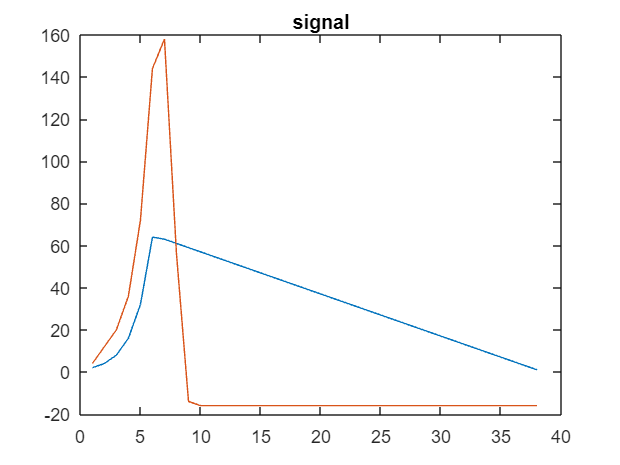


hold on
plot(filtered)

Did you expect this result? Did padding take place?

Because the filtered signal was a of size 37 instead of 38, there is likely padding that happened. indeed, when looking at the drop to -16, it is likely that padding to the last value of the original value was used.

## Question 1.8

Redo it with filtfilt

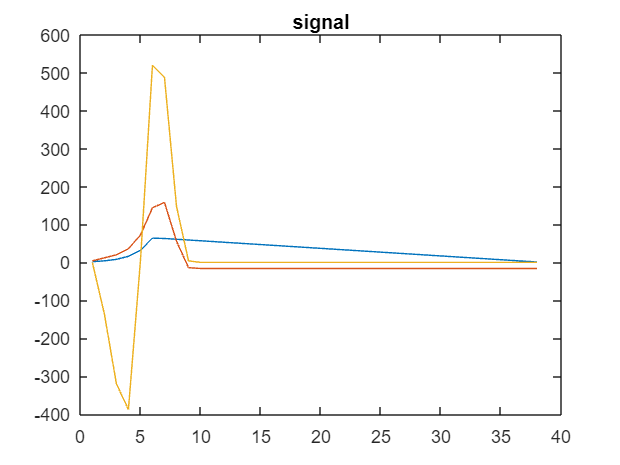

% code goes here
filtered2 = filtfilt(f, 1, s);
hold on
plot(filtered2)

What does this function do?

!!!!!! NOT FROM ME:

In summary, the key difference lies in how the filtering is performed with respect to phase distortion. `filter` introduces phase distortion in the forward direction, while `filtfilt` aims to eliminate phase distortion by filtering the data in both forward and backward directions. The choice between them depends on the specific requirements of your application and whether phase distortion is a critical factor.

## Question 1.9

Load the data

load mandrill

plot it

figure
subplot(1,2,1)
% plotting goes here
imagesc(X)
title original image
colormap gray
axis image

Apply the filter, and plot the result. Ensure that you understand what everything does including the kron command. This is a little piece of Matlab magic

h1=gausswin(20); %creating a Gaussian window of size 20
h2=kron(h1,h1'); %Kronecker tensor product :  product of two matrices A and B is denoted by kron(A, B) and produces a block matrix where each element of A is multiplied by the entire matrix B. 
% (here, the two matrices are h1 and its transpose h1')

% Apply the filters
filtered = filter2(h2, X)

filtered = 1.0e+04 *

    0.1516    0.1742    0.1945    0.2127    0.2291    0.2451    0.2614    0.2786    0.2969    0.3152    0.3330    0.3502    0.3665    0.3808    0.3943    0.4069    0.4206    0.4357    0.4516    0.4674    0.4816    0.4913    0.4954    0.4946    0.4902    0.4834    0.4758    0.4689    0.4637    0.4614    0.4620    0.4662    0.4757    0.4917    0.5126    0.5365    0.5601    0.5810    0.5980    0.6102    0.6181    0.6236    0.6279    0.6305    0.6322    0.6319    0.6290    0.6226    0.6124    0.5987
    0.1837    0.2110    0.2352    0.2569    0.2766    0.2959    0.3158    0.3375    0.3610    0.3852    0.4090    0.4325    0.4547    0.4741    0.4918    0.5075    0.5232    0.5397    0.5562    0.5725    0.5871    0.5972    0.6013    0.5999    0.5943    0.5858    0.5761    0.5668    0.5591    0.5545    0.5531    0.5560    0.5653    0.5823    0.6059    0.6337    0.6622    0.6881    0.7099    0.7263    0.7374    0.7453    0.7514    0.7553    0.7576    0.7573    0.7535    0.7

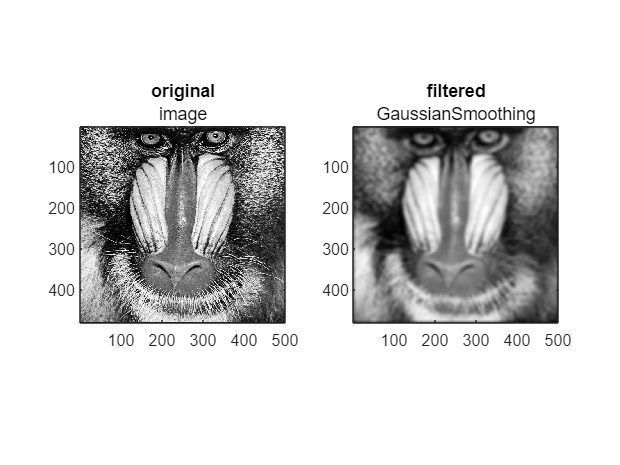

subplot(1,2,2)
% Plot the result
imagesc(filtered)
title filtered GaussianSmoothing
axis image

Observing the impact of a Gaussian window reveals its ability to create a smoothing effect. Functioning as a low-pass filter, Gaussian blur minimizes variations in pixel values by eliminating extreme outliers in an image. The Gaussian function incorporates spatial correlations among pixels, while its inverse helps retain edge features. Larger Gaussian window sizes result in more pronounced blurring of the image.